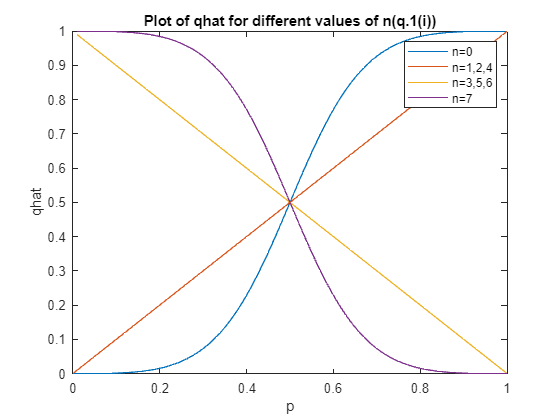

% Question 1
%(i)
p = 0:0.01:1;
lamda_1 = (1 - p) ./ p;
% Plot for n = 0
qhat = 1 ./ (1 + ((lamda_1).^3));
plot(p, qhat);
hold on;
% Plot for n = 1, 2, 4
qhat = 1 ./ (1 + lamda_1);
plot(p, qhat);
hold on;
% Plot for n = 3, 5, 6
qhat = lamda_1 ./ (1 + lamda_1);
plot(p, qhat);
hold on;
% Plot for n = 7
qhat = (lamda_1.^3) ./ (1 + ((lamda_1).^3));
plot(p, qhat);
hold off;
legend('n=0', 'n=1,2,4', 'n=3,5,6', 'n=7');
xlabel('p');
ylabel('qhat');
title('Plot of qhat for different values of n(q.1(i))');

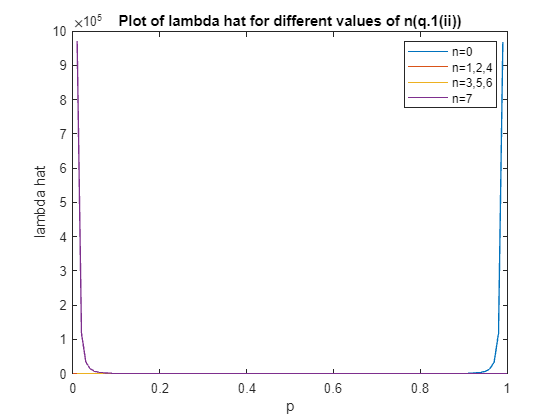

%(ii)
p = 0:0.01:1;
lamda_1 = (1 - p) ./ p;
% Plot for n = 0
lamdahat = 1 ./ (lamda_1.^3);
plot(p, lamdahat);
hold on;
% Plot for n = 1, 2, 4
lamdahat = 1 ./ (lamda_1);
plot(p, lamdahat);
% Plot for n = 3, 5, 6
lamdahat = lamda_1;
plot(p, lamdahat);
% Plot for n = 7
lamdahat = (lamda_1.^3);
plot(p, lamdahat);
hold off;
legend('n=0', 'n=1,2,4', 'n=3,5,6', 'n=7');
xlabel('p');
ylabel('lambda hat');
title('Plot of lambda hat for different values of n(q.1(ii))');

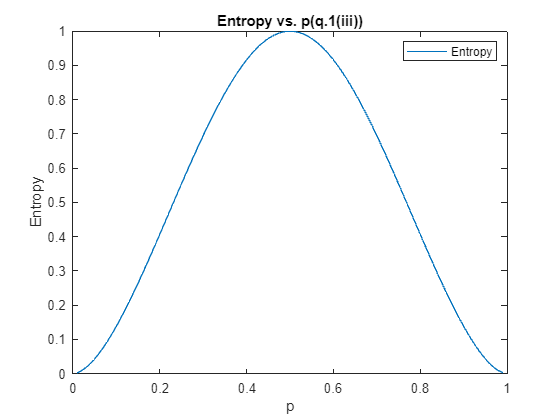

%(iii)
%Question 1(iii)
p = 0:0.01:1;
entropy = -(p.*log2(p) + (1-p).*log2(1-p));
entropy = 3*(1-p).*p.*entropy;
entropy = entropy - (p.^3).*(log2((p.^3)./(p.^3+((1-p).^3))));
entropy = entropy - ((1-p).^3).*log2(((1-p).^3)./(p.^3+((1-p).^3)));
plot(p, entropy);
hold off;
legend('Entropy');
xlabel('p');
ylabel('Entropy');
title('Entropy vs. p(q.1(iii))');

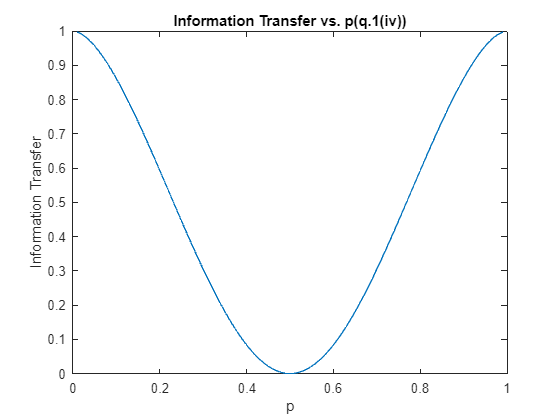

%(iv)
plot(p,1-entropy);
xlabel('p');
ylabel('Information Transfer');
title('Information Transfer vs. p(q.1(iv))');

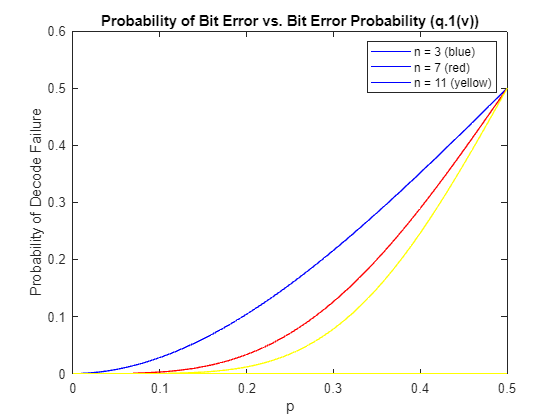

%(v)
p = 0:0.01:0.5;
N_values = [3 7 11];
for n = N_values
  q = zeros(length(p));
  for i = (n/2) + 0.5:1:n
    b = binopdf(i, n, p);
    for j = 1:length(p)
      q(j) = q(j) + b(j);
    end
  end
  if n == N_values(1)  % n = 3
    plot(p, q, 'Color', 'blue');
  elseif n == N_mat(2) % n = 7
    plot(p, q, 'Color', 'red');
  else                 % n = 11
    plot(p, q, 'Color', 'yellow');
  end
  hold on;
end

legend({'n = 3 (blue)', 'n = 7 (red)', 'n = 11 (yellow)'});
xlabel('p');
ylabel('Probability of Decode Failure');
title('Probability of Bit Error vs. Bit Error Probability (q.1(v))');
hold off;

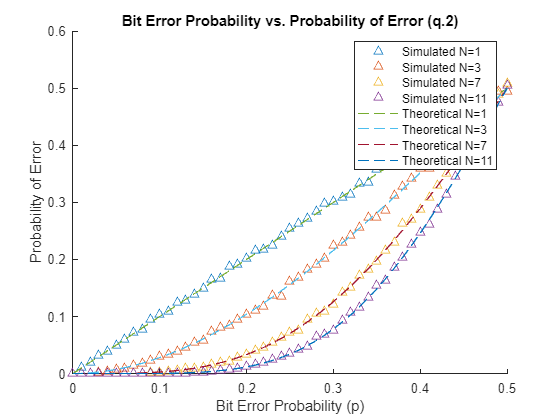

% Question 2
N_values = [1, 3, 7, 11];
pth = 0:0.01:0.5; % Theoretical values of p
Ntxbits = 10000;
Perror = zeros(length(pth), length(N_values));
p_theory = zeros(length(pth), length(N_values));
legends = cell(1, 2 * length(N_values));
figure;
hold on;
% Simulated
for j = 1:length(N_values)
    N = N_values(j);
    NcodedBits = N * Ntxbits;
    s_tx_gen = randi([0, 1], 1, Ntxbits);
    s_tx = reshape(repmat(s_tx_gen, N, 1), 1, []);
    i = 1;
    for kp = pth
        bsc_noise = rand(1, NcodedBits) > (1 - kp);
        r_gen = xor(s_tx, bsc_noise);
        r = reshape(r_gen, [], Ntxbits);
        sum_r = sum(r, 1);
        s_tx_decoded = sum_r > (N / 2);
        N_err = xor(s_tx_gen, s_tx_decoded);
        Pe = sum(N_err) / Ntxbits;
        Perror(i, j) = Pe;
        i = i + 1;
    end
    plot(pth, Perror(:, j), '^', 'MarkerFaceColor', 'none');
    legends{j} = sprintf('Simulated N=%d', N);
end
% Theoretical
for j = 1:length(N_values)
    N = N_values(j);
    t = floor(N/2);
    for k = 1:length(pth)
        pe = 0;
        for i = t+1:N
            pe = pe + nchoosek(N,i) * pth(k)^i * (1-pth(k))^(N-i);
        end
        p_theory(k,j) = pe;
    end
    plot(pth, p_theory(:, j), '--');
    legends{length(N_values)+j} = sprintf('Theoretical N=%d', N);
end
hold off;
legend(legends);
xlabel('Bit Error Probability (p)');
ylabel('Probability of Error');
title('Bit Error Probability vs. Probability of Error (q.2)');

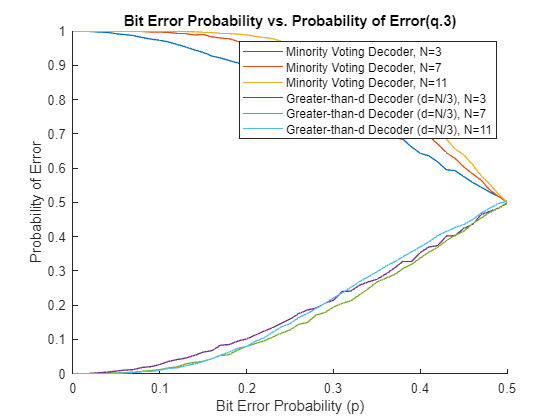

% Question 3
N_values = [3, 7, 11];
p = 0:0.01:0.5;
Ntxbits = 10000;

figure;
hold on;
legends = cell(1, length(N_values)*2);
for toggle = 1:2 
    Perror = zeros(length(p), length(N_values));
    for j = 1:length(N_values)
        N = N_values(j);
        NcodedBits = N * Ntxbits;
        s_tx_gen = randi([0, 1], 1, Ntxbits);
        s_tx = reshape(repmat(s_tx_gen, N, 1), 1, []);
        i = 1;
        for kp = p
            bsc_noise = rand(1, NcodedBits) > (1 - kp);
            r_gen = xor(s_tx, bsc_noise);
            r = reshape(r_gen, [], Ntxbits);
            sum_r = sum(r, 1);
            % Decoding logic
            if toggle == 1
                s_tx_decoded = sum_r < (N / 2); % Minority Voting Decoder
            else
                d = N / 3; % Greater-than-d Decoder with d=N/2          
                s_tx_decoded = sum_r > d;
            end
            N_err = xor(s_tx_gen, s_tx_decoded);
            Pe = sum(N_err) / Ntxbits;
            Perror(i, j) = Pe;
            i = i + 1;
        end
        plot(p, Perror(:, j));
        if toggle == 1
            legends{(toggle-1)*length(N_values) + j} = sprintf('Minority Voting Decoder, N=%d', N);
        else
            legends{(toggle-1)*length(N_values) + j} = sprintf('Greater-than-d Decoder (d=N/3), N=%d', N);
        end
    end
end
hold off;

legend(legends);
xlabel('Bit Error Probability (p)');
ylabel('Probability of Error');
title('Bit Error Probability vs. Probability of Error(q.3)');

% Below plot is to show that among the three schemes majority-vote-decoding is better
% We can change the value of d(d<N/2) and see that for all such values of d the bit error probability is least for majority vote decoder

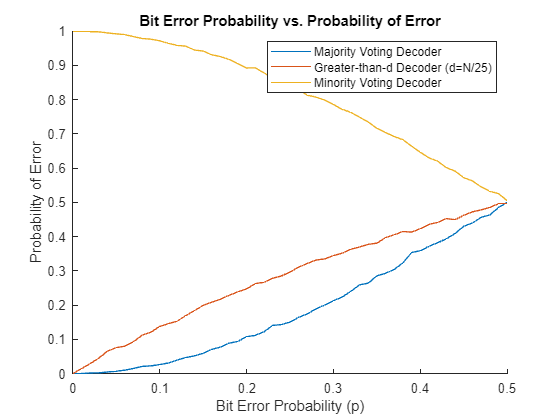

N_values = 3;
p = 0:0.01:0.5;
Ntxbits = 10000;

figure;
hold on;
legends = cell(1, 3);
for decoder_idx = 1:3 % Iterate over three decoders
    Perror = zeros(length(p), 1);
    decoder_label = '';
    if decoder_idx == 1
        decoder_label = 'Majority Voting Decoder';
    elseif decoder_idx == 2
        decoder_label = 'Greater-than-d Decoder (d=N/25)';
    else
        decoder_label = 'Minority Voting Decoder';
    end
    N = N_values;
    NcodedBits = N * Ntxbits;
    s_tx_gen = randi([0, 1], 1, Ntxbits);
    s_tx = reshape(repmat(s_tx_gen, N, 1), 1, []);
    i = 1;
    for kp = p
        bsc_noise = rand(1, NcodedBits) > (1 - kp);
        r_gen = xor(s_tx, bsc_noise);
        r = reshape(r_gen, [], Ntxbits);
        sum_r = sum(r, 1);
        % Decoding logic
        if decoder_idx == 1
            s_tx_decoded = sum_r > (N / 2); % Majority Voting Decoder
        elseif decoder_idx == 2
            d = N / 25; % Greater-than-d Decoder with d=N/2
            s_tx_decoded = sum_r > d;
        else
            s_tx_decoded = sum_r < (N / 2); % Minority Voting Decoder
        end
        N_err = xor(s_tx_gen, s_tx_decoded);
        Pe = sum(N_err) / Ntxbits;
        Perror(i) = Pe;
        i = i + 1;
    end
    plot(p, Perror);
    legends{decoder_idx} = sprintf('%s', decoder_label);
end

hold off;

legend(legends);
xlabel('Bit Error Probability (p)');
ylabel('Probability of Error');
title('Bit Error Probability vs. Probability of Error');

% No, typically you would not expect better performance than the majority-voting decoder with the repetition code.
% The majority-voting decoder is based on Bayesian detection theory and is quite effective for symmetric binary channels like the binary symmetric channel (BSC)
% The majority-voting decoder essentially exploits the fact that in a repetition code, if the majority of the received bits are correct, then the decoded bit is likely to be correct. This decoder tends to perform well because it makes decisions based on the statistical likelihood of each bit being flipped by noise.